%% Pitch angle and position Loop PID Tuning
clc; clear; close all;

%% Parameters
m = 1.5; Cv = 0.1; Cw = 0.01; Jy = 3e-2; g = 9.81;
Ts = 0.0005;                % 0.5 ms

s = tf('s');

% Plants
G_inner_c = 1/(Jy*s + Cw);          % M -> w
G_inner   = c2d(G_inner_c, Ts, 'zoh');

G_phi     = c2d(1/s, Ts, 'tustin');  % w -> phi
G_vphi    = c2d(g/s, Ts, 'tustin');  % phi -> v (small-angle)
G_x       = c2d(1/s, Ts, 'tustin');  % v -> x

%% Tunable PIDs
C_rate  = tunablePID('C_rate','PID');  C_rate.Ts  = Ts;
C_angle = tunablePID('C_angle','PID'); C_angle.Ts = Ts;
C_vel   = tunablePID('C_vel','PID');   C_vel.Ts   = Ts;   % you can change to 'PI'
C_pos   = tunablePID('C_pos','P');     C_pos.Ts   = Ts;   % change to 'PI' if you want zero SSE in x

% Constraints
C_rate.Kp.Minimum = 0;  C_rate.Ki.Minimum = 0;  C_rate.Kd.Minimum = 0; 
C_rate.Tf.Minimum=10; C_rate.Tf.Maximum=1000;

C_angle.Kp.Minimum = 0;  C_angle.Ki.Minimum = 0;  C_angle.Kd.Minimum = 0; 
C_angle.Tf.Minimum=10; C_angle.Tf.Maximum=1000;

C_vel.Kp.Minimum = 0;  C_vel.Ki.Minimum = 0;  C_vel.Kd.Minimum = 0; 
C_vel.Tf.Minimum=10; C_vel.Tf.Maximum=1000;

C_pos.Kp.Minimum = 0;

%% Signal naming & summing junctions
% Controllers
C_pos.InputName   = 'e_x';     C_pos.OutputName   = 'v_ref';
C_vel.InputName   = 'e_v';     C_vel.OutputName   = 'phi_ref';
C_angle.InputName = 'e_phi';   C_angle.OutputName = 'w_ref';
C_rate.InputName  = 'e_w';     C_rate.OutputName  = 'M_ctrl';

% Plants
G_x.InputName     = 'v';       G_x.OutputName     = 'x';
G_vphi.InputName  = 'phi';     G_vphi.OutputName  = 'v';
G_phi.InputName   = 'w';       G_phi.OutputName   = 'phi';
G_inner.InputName = 'M';       G_inner.OutputName = 'w';

% Errors
Sum_x   = sumblk('e_x   = x_ref   - x');
Sum_v   = sumblk('e_v   = v_ref   - v');
Sum_phi = sumblk('e_phi = phi_ref - phi');
Sum_w   = sumblk('e_w   = w_ref   - w');

% For tuning: plant torque equals controller torque (no disturbance)
Sum_M_nom = sumblk('M = M_ctrl');

%% Interconnection FOR TUNING (no M_dist here)
% Expose x,v,phi,w so we can analyze their step responses to x_ref
CL0 = connect(C_pos,C_vel,C_angle,C_rate, ...
              G_x,G_vphi,G_phi,G_inner, ...
              Sum_x,Sum_v,Sum_phi,Sum_w,Sum_M_nom, ...
              'x_ref', {'x','v','phi','w'}, ...
              {'e_x','e_v','e_phi','e_w','M','w_ref'});

%% Tuning goals
% Outer position tracking
ReqTrackPos = TuningGoal.Tracking('x_ref','x',0.6);

% Loop-shape bandwidth targets (use STABLE weights!):
% makeweight(g0, wc, ginf) gives a stable, min-phase template
wc_rate  = 2*pi*6;     % ~6 Hz
wc_angle = 2*pi*2;     % ~2 Hz
wc_vel   = 2*pi*0.6;   % ~0.6 Hz
wc_pos   = 2*pi*0.2;   % ~0.2 Hz

W_rate   = makeweight(30, wc_rate, 0.03);   % high DC gain, roll-off above wc
W_angle  = makeweight(20, wc_angle, 0.05);
W_vel    = makeweight(10, wc_vel,   0.1);
W_pos    = makeweight(5,  wc_pos,   0.2);

ReqLS_rate  = TuningGoal.LoopShape('e_w',   W_rate);
ReqLS_angle = TuningGoal.LoopShape('e_phi', W_angle);
ReqLS_vel   = TuningGoal.LoopShape('e_v',   W_vel);
ReqLS_pos   = TuningGoal.LoopShape('e_x',   W_pos);

% Sensitivity shaping (low-frequency disturbance rejection) – STABLE weights
wr_rate  = 2*pi*3;    % strong rejection below ~3 Hz (rate)
wr_angle = 2*pi*1;    % strong rejection below ~1 Hz (angle)
ReqSensRate  = TuningGoal.Sensitivity('e_w',   1/(1 + s/wr_rate));
ReqSensAngle = TuningGoal.Sensitivity('e_phi', 1/(1 + s/wr_angle));

GOALS = [ReqTrackPos, ReqLS_rate, ReqLS_angle, ReqLS_vel, ReqLS_pos, ...
         ReqSensRate, ReqSensAngle];

%% Tune
[CLtuned,fSoft] = systune(CL0, GOALS);

Final: Failed to enforce closed-loop stability (max |z| = 1)
Failed to stabilize closed-loop system. Try different initial values or increase the number of random starts using "systuneOptions".



%% Show tuned gains
disp('--- Tuned controllers ---');

--- Tuned controllers ---


showTunable(CLtuned)

C_angle =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 0.000118, Ki = 1.4e-10, Kd = 8.9e-05, Tf = 11.1, Ts = 0.0005
 
Name: C_angle
Sample time: 0.0005 seconds
Discrete-time PIDF controller in parallel form.
-----------------------------------
C_pos =
 
  Kp = 9.87e-07
 
Name: C_pos
P-only controller.
-----------------------------------
C_rate =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 0.000602, Ki = 7.35e-10, Kd = 6.12e-05, Tf = 11.1, Ts = 0.0005
 
Name: C_rate
Sample time: 0.0005 seconds
Discrete-time PIDF controller in parallel form.
-----------------------------------
C_vel =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 0.000128, Ki = 1.65e-10, Kd = 4.01e-05, Tf = 11.1, Ts = 0.0005
 
Name: C_vel
Sample time: 0.0005 seconds
Discret

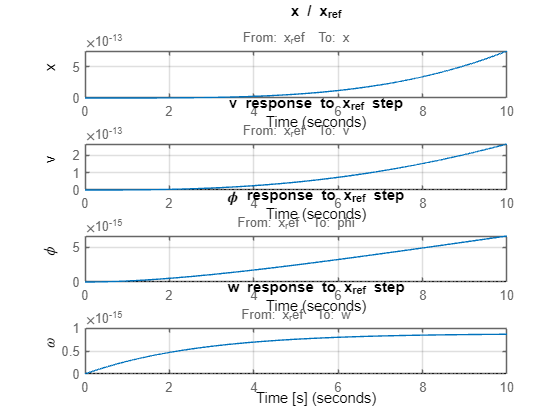

%% Closed-loop responses to position step (see internal states too)
T_x   = getIOTransfer(CLtuned,'x_ref','x');
T_v   = getIOTransfer(CLtuned,'x_ref','v');
T_phi = getIOTransfer(CLtuned,'x_ref','phi');
T_w   = getIOTransfer(CLtuned,'x_ref','w');

figure;
subplot(4,1,1); step(T_x,  10); grid on; ylabel('x');   title('x / x_{ref}');
subplot(4,1,2); step(T_v,  10); grid on; ylabel('v');   title('v response to x_{ref} step');
subplot(4,1,3); step(T_phi,10); grid on; ylabel('\phi'); title('\phi response to x_{ref} step');
subplot(4,1,4); step(T_w,  10); grid on; ylabel('\omega');   xlabel('Time [s]'); title('w response to x_{ref} step');

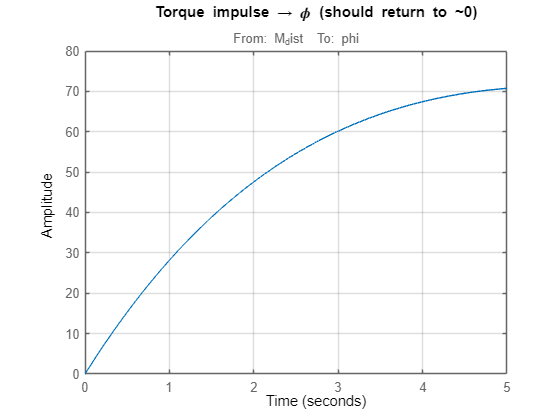


%% Disturbance rejection at angle: torque impulse -> phi
% Build a SECOND interconnection with disturbance
Sum_M   = sumblk('M = M_ctrl + M_dist');
CLd = connect(C_pos,C_vel,C_angle,C_rate, ...
              G_x,G_vphi,G_phi,G_inner, ...
              Sum_x,Sum_v,Sum_phi,Sum_w,Sum_M, ...
              {'x_ref','M_dist'}, {'phi','w'});

T_phi_dist = getIOTransfer(CLd,'M_dist','phi');
T_w_dist   = getIOTransfer(CLd,'M_dist','w');

figure; impulse(T_phi_dist,5); grid on; title('Torque impulse → \phi (should return to ~0)');

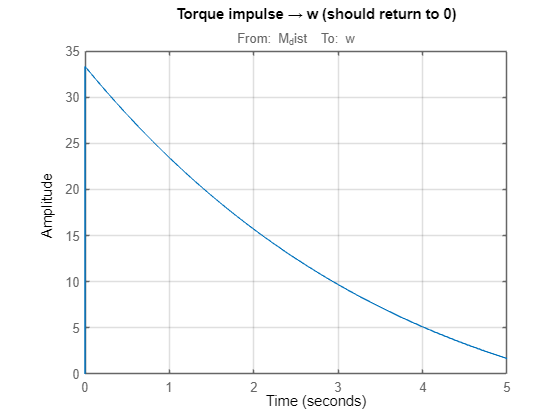

figure; impulse(T_w_dist,5);   grid on; title('Torque impulse → w (should return to 0)');


%% Optional: Open-loop checks
L_rate  = getLoopTransfer(CLtuned,'e_w',-1);
L_angle = getLoopTransfer(CLtuned,'e_phi',-1);
L_vel   = getLoopTransfer(CLtuned,'e_v',-1);
L_pos   = getLoopTransfer(CLtuned,'e_x',-1);

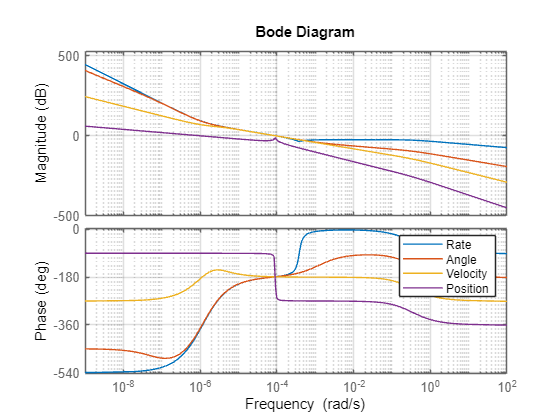

figure;
h = bodeplot(L_rate, L_angle, L_vel, L_pos); grid on;
legend({'Rate','Angle','Velocity','Position'});